# Inverted Pendulum

clearvars; clc; close all
addpath("matlab_tools") % Add matlab_tools to path
%set(groot,'defaultFigurePosition',[0 0 900 900])

## Data

L = 0.3; % pendulum length (m)
M = 0.5; % mass of cart (kg)
m = 0.2; % mass of pendulum (kg)
b = 0.1; % friction coefficient for cart
max_F = 10; % max allowed force (N)
rail_length = 1;  % length of the rail
cart_length = 0.2; % length of the cart
I = 0.006; % traagheidsmoment
g = 9.81; % valversnelling

## Matrices opstellen

N = I*(M+m) + M*m*L^2;
A = [0 1 0 0;
    0 -(I+m*L^2)*b/N m^2*g*L^2/N 0;
    0 0 0 1;
    0 -m*L*b/N m*g*L*(M+m)/N 0];
B = [0;
    (I+m*L^2)/N;
    0;
    m*L/N];
C = [1 0 0 0;
    0 0 1 0];
D = [0;
    0];
states = {'x' 'v' 'theta' 'w'};
inputs = {'u'};
outputs = {'x'; 'theta'};
S = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);
% Kleine coeff nog naar 0 zetten


## Controleerbaarheid

rank(ctrb(A,B)) == 4

ans = logical
   1


## Observeerbaarheid

rank(obsv(A,C)) == 4

ans = logical
   1


## Startup Python

if ispc % Check for Windows OS
    system('closeSessions.bat');
    pause(1)
    system('start cmd /k "title SYSTEM & python system.py"');
    system('start cmd /k "title CONTROLLER & python controller.py"');
end

 
C:\Users\alexv\Documents\Alex\KMS\3 BA POL\ES323\Inverted Pendulum\arduino>title Closing SYSTEM and CONTROLLER sessions...  
 
C:\Users\alexv\Documents\Alex\KMS\3 BA POL\ES323\Inverted Pendulum\arduino>for /F "tokens=2" %A in ('tasklist /v /fi "imagename eq cmd.exe" |findstr /l /c:"SYSTEM" /c:"CONTROLLER"') do taskkill /pid %A  
 
C:\Users\alexv\Documents\Alex\KMS\3 BA POL\ES323\Inverted Pendulum\arduino>taskkill /pid 13508  
SUCCESS: Sent termination signal to the process with PID 13508. 
^C

% Standard modes (must correspond to similar mode in Arduino code)
OPEN_LOOP   = 0;
CLASSICAL_ANG   = 1; % Classical (PID family) controller for angle
CLASSICAL_COMB   = 2; % For angle and position
OBSERVER_TEST = 3;
STATE_SPACE = 4;
EXTENDED    = 5;

## Open Lus

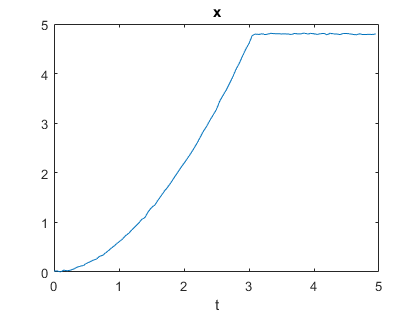

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 60);

% Define parameters and modes
Ts = 0.05; % Sample time
n_samples = 100;
ts = (0:n_samples-1)*Ts;

mode = OPEN_LOOP;
w = 1;
set_mode_params(arduino, mode, w, [])
reset_system(arduino)
Y = get_response(arduino, w, n_samples);

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
figure; plot(ts, x); title("x"); xlabel('t')

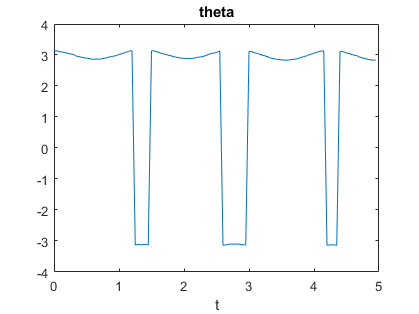

figure; plot(ts, theta); title("theta"); xlabel('t')

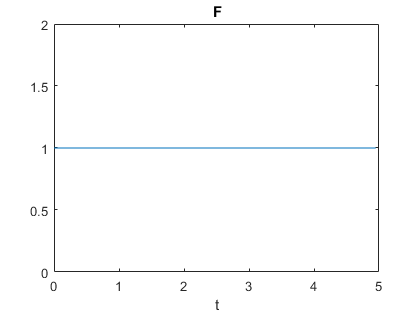

figure; plot(ts, u); title("F"); xlabel('t')


close_connection(arduino)
clear arduino

## Classical Controller

Hoek

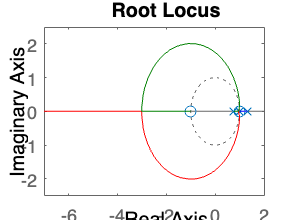

Ts = 0.05; % Sample time
Sd = c2d(S,Ts); % Discretiseren
Sdtf = tf(Sd); % We nemen de transferfunctie zodat we verder kunnen werken
% met enkel de transferfunctie van theta => SISO

% Zonder regelaar
rlocus(Sd(2))

ps2 = pole(Sdtf(2)) % Het berekenen van de polen voor theta

ps2 =     1.3210
    0.9929
    0.7555


zs2 = zero(Sdtf(2)) % Het berekenen van de nulpunten voor theta

zs2 =     1.0000
   -0.9970


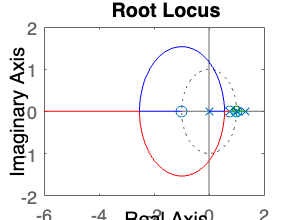


% Regelaar
Rd2 = zpk([ps2(2:end)],[0,1.04],48.1,Ts); % Implementatie van een eerste PID
% Nulpunten:
%   Nulpunten leggen op de polen binnen de eenheidscirkel zodat ze niet meer
%   zullen bewegen voor een variabele gain. Op de buitenste wordt er geen
%   nulpunt gelegd zodat het systeem kan gestabiliseerd worden.
% 
% Polen:
%   Er wordt een pool in 1.04 (arbitrair, maar wel nog steeds tussen de rechts uiterste pool
%   en het rechtse uiterste nulpunt) geplaatst. Die pool zal ervoor zorgen
%   dat de rootlocus wijzigt. Door de nieuwe vorm van de rootlocus is het
%   mogelijk adhv de gain de polen binnen de eenheidscirkel te plaatsen.
%   Door het criterium X hebben we een extra pool nodig. We plaatsen de
%   pool in 0 zodat we een snelle pool hebben. Het voordeel van de snelle
%   pool.
% 
% Gain:
%   We wensen de polen binnen de eenheidscirkel te plaatsen en kiezen
%   ervoor om deze eveneens op de reële as te laten vallen teneinde geen
%   imaginair component te verkrijgen. Daardoor wordt het oscillair gedrag
%   vermeden. Om de waarde van de gain te bepalen werd de rootlocus geplot
%   en de gain bepaald op de positie waar de twee rechtse krommes elkaar
%   binnen de eenheidscirkel raken. We vinden dat een gain van 48.1
%   vereist is en steken deze onmiddelijk in de definitie van Rd2.
rlocus(Rd2*Sd(2))


% We zullen geen zero-static-error controller implementeren voor de hoek.
% Dit zou overeenkomen met het plaatsen van een pool in 1.
% Een zero-static-error controller is gewenst indien er een stap aangelegd
% wordt. Dit zullen we nooit doen voor de hoek, wegens de fysische limieten
% voor de positie van het karretje. Het ontwerp van een zero-static-error
% controller voor de controle van de positie van het karretje is
% daarentegen wel een optie, gezien we hier wel een stap aan zullen leggen.

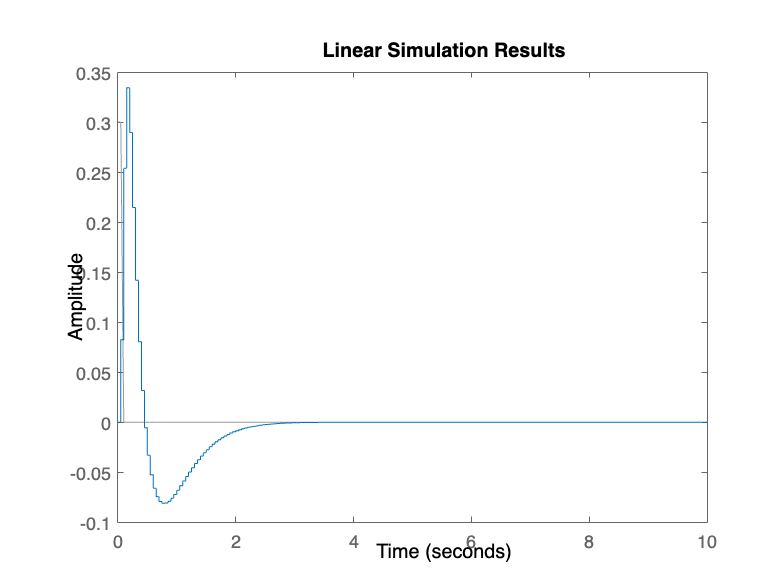

t = 0:Ts:10;
% Er worden geen impulsen of stappen aangelegd aangezien de hoek in
% realiteit niet zo'n verloop heeft. Daarom wordt gebruikgemaakt van lsim.
lsim(feedback(Rd2*Sdtf(2),1),[0.3 0.3 zeros(1,length(t)-2)],t) % Output y

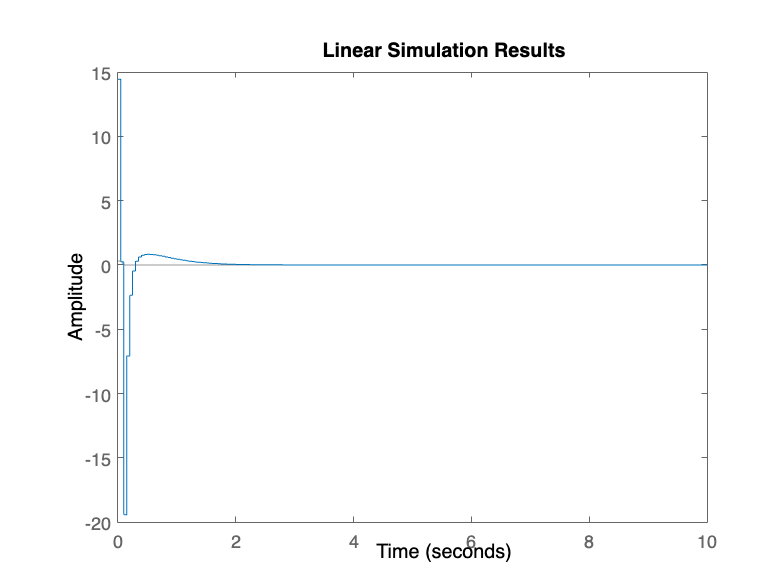

lsim(feedback(Rd2,Sdtf(2)),[0.3 0.3 zeros(1,length(t)-2)],t) % Kracht F

SdCl_hoek_Loop = minreal(feedback(Rd2*Sdtf,[0 1]))

SdCl_hoek_Loop =
 
  From input "u" to output...
        0.10914 (z+0.997) (z-0.7807) (z-1.281)
   x:  ----------------------------------------
       (z-1) (z-0.3718) (z^2 - 1.715z + 0.7354)
 
                0.27425 (z+0.997) (z-1)
   theta:  ----------------------------------
           (z-0.3718) (z^2 - 1.715z + 0.7354)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



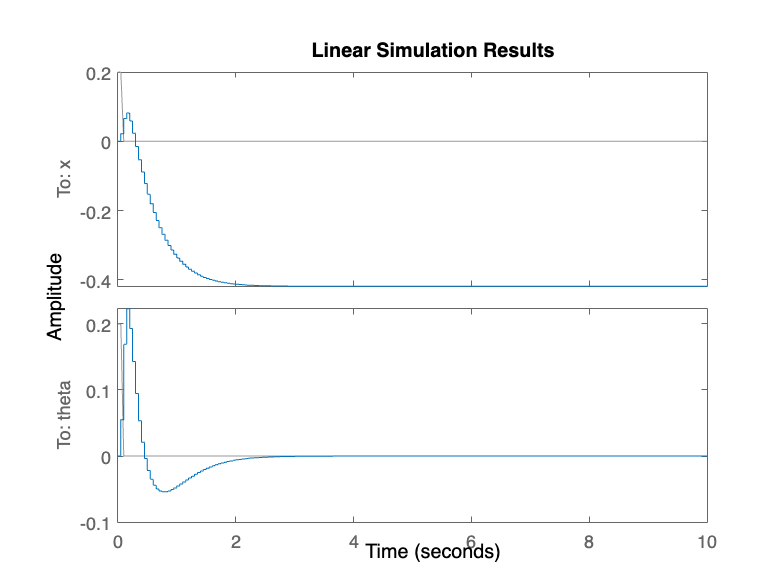

% Minreal vereenvoudigt de uitdrukking om het overzicht te bewaren.
% Enkel een feedback plaatsen op de hoek door [0 1]
lsim(minreal(feedback(Rd2*Sdtf,[0 1])),[0.2 0.2 zeros(1,length(t)-2)],t)

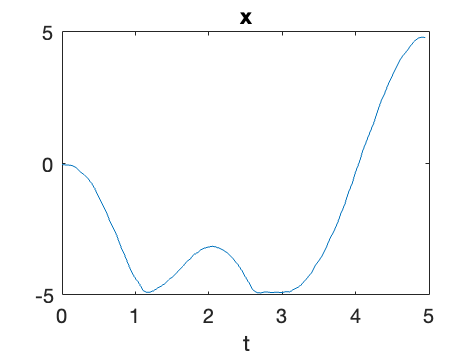

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 10^3);

% Define parameters and modes
n_samples = 10^2;
ts = (0:n_samples-1)*Ts;

mode = CLASSICAL_ANG;
w = 0.0;
[~,G2] = zero(Rd2);
set_mode_params(arduino, mode, w, cat(1, G2, cat(1, zero(Rd2), pole(Rd2))));
reset_system(arduino);
Y = get_response(arduino, w, n_samples);

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
figure; plot(ts, x); title("x"); xlabel('t')

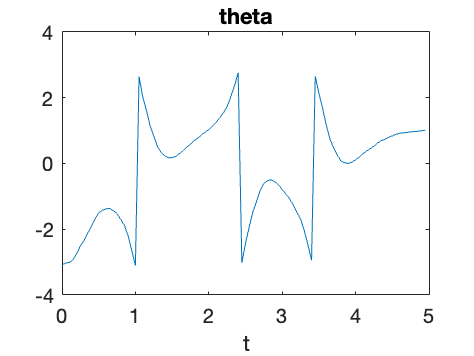

figure; plot(ts, theta); title("theta"); xlabel('t')

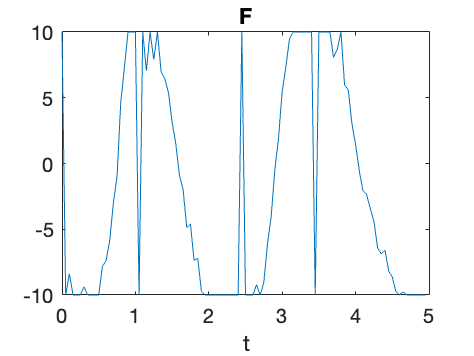

figure; plot(ts, u); title("F"); xlabel('t')

% Soms verschijnt er een initiële piek voor de kracht (F). Gezien dit
% slechts om een piek gaat vormt dit geen probleem. Het werkelijke systeem
% (met een limitatie op de kracht) zal zich misschien licht anders
% gedragen, maar de hoek zal toch gestabiliseerd worden.

close_connection(arduino)
clear arduino

Positie (v1) - Niet Causaal

% Enkel de transferfunctie van x (positie) beschouwen => SISO
Sdtf(1)

ans =
 
  From input "u" to output "x":
  0.002269 z^3 - 0.002416 z^2 - 0.002395 z + 0.002262
  ---------------------------------------------------
     z^4 - 4.069 z^3 + 6.129 z^2 - 4.051 z + 0.991
 
Sample time: 0.05 seconds
Discrete-time transfer function.



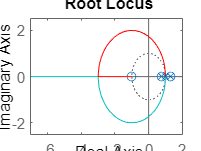


% Zonder regelaar
rlocus(Sd(1))

ps1 = pole(Sdtf(1)) % Het berekenen van de polen voor x

ps1 =     1.3210
    1.0000
    0.9929
    0.7555


% We merken op dat er reeds een pool op 1 ligt. Dit maakt dat voor de
% controle van de positie er automatisch zero-statische fout is VOOR HET SYSTEEM.
% MAAR: Nog niet voor de perturbaties een zero-static-error. Hiervoor zou
% er een pool in de regelaar moeten zijn.
zs1 = zero(Sdtf(1)) % Het berekenen van de nulpunten voor x

zs1 =    -0.9970
    1.2810
    0.7807


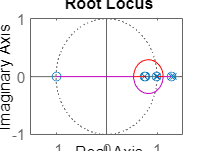


% Regelaar
Rd1 = zpk([ps1(3:4)],[zs1(2)],428,Ts); % Implementatie van een tweede PID
% Polen:
%   Om de pool rechts buiten de eenheidscirkel naar binnen te krijgen
%   plaatsen we een pool op het nulpunt rechts buiten de eenheidscirkel.
%   Deze zal vastgehouden worden door het nulpunt dat er ligt.% 
% Nulpunten:
%   Om de pool die van rechts komt en een imaginaire component krijgt
%   binnen de eenheidscirkel te trekken plaatsen we twee nulpunten in de
%   eenheidscirkel (1 was niet voldoende om de takken erin te krijgen). 
% Gain:
%   We wensen de polen binnen de eenheidscirkel te plaatsen en kiezen
%   ervoor om deze eveneens op de reële as te laten vallen teneinde geen
%   imaginair component te verkrijgen. Daardoor wordt het oscillair gedrag
%   vermeden. Om de waarde van de gain te bepalen werd de rootlocus geplot
%   en de gain bepaald op de positie waar de twee rechtse krommes elkaar
%   binnen de eenheidscirkel raken. We vinden dat een gain van 428
%   vereist is en steken deze onmiddelijk in de definitie van Rd1.
rlocus(Rd1*Sd(1))

% Probleem: Meer nulpunten dan polen in controller -> systeem F->y zal niet
% causaal zijn. Zie verder.

SdCl_pos_Loop = minreal(feedback(Rd1*Sdtf,[1 0]))

SdCl_pos_Loop =
 
  From input "u" to output...
       0.49268 (z+0.997) (z-0.7807)
   x:  ----------------------------
         (z^2 - 1.071z + 0.2867)
 
                1.238 (z+0.997) (z-1)^2
   theta:  ---------------------------------
           (z-1.281) (z^2 - 1.071z + 0.2867)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



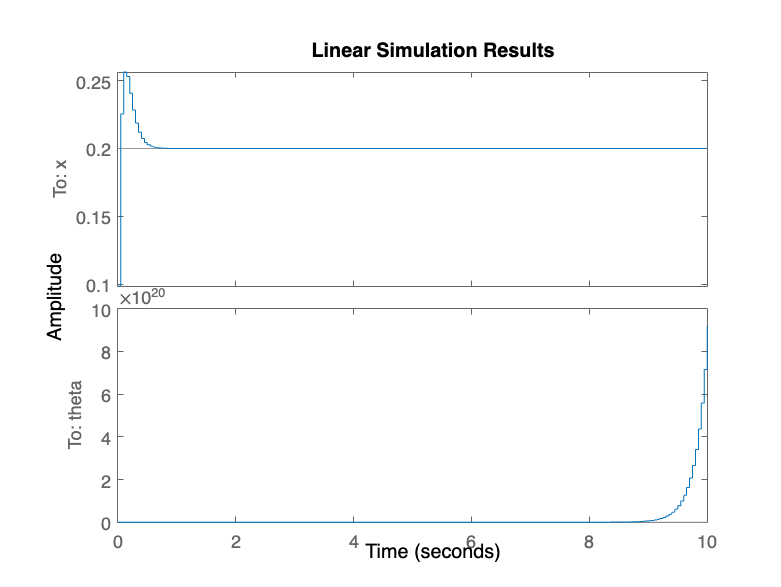

% Minreal vereenvoudigt de uitdrukking om het overzicht te bewaren.
% Enkel een feedback plaatsen op de positie door [1 0]
t = 0:Ts:10;
lsim(minreal(feedback(Rd1*Sdtf,[1 0])),[0.2 0.2 0.2*ones(1,length(t)-2)],t)

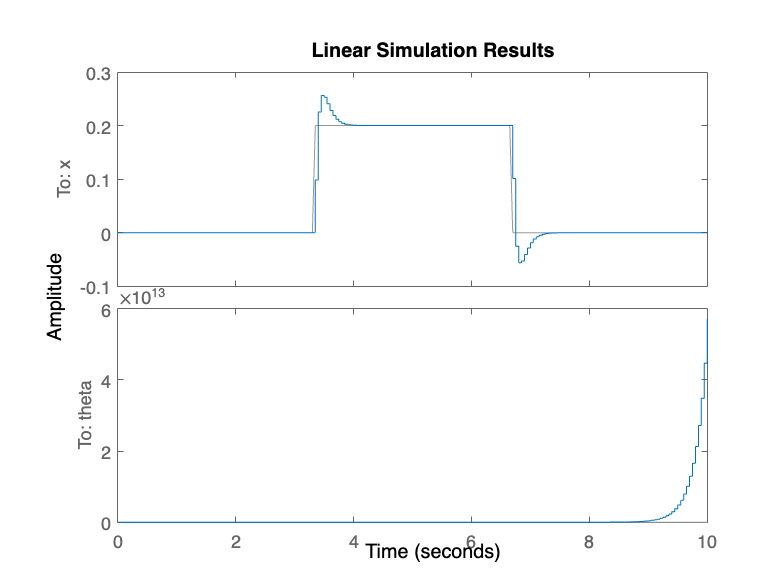

lsim(minreal(feedback(Rd1*Sdtf,[1 0])),[zeros(1,length(t)/3) 0.2*ones(1,length(t)/3) zeros(1,length(t)/3)],t)

% Het systeem volgt de opgelegde waarde.

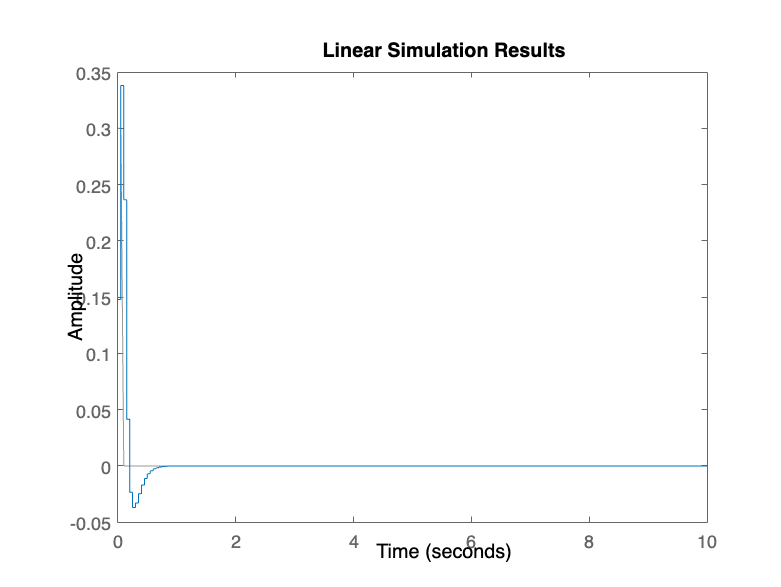

% Er worden geen impulsen of stappen aangelegd aangezien de hoek in
% realiteit niet zo'n verloop heeft. Daarom wordt gebruikgemaakt van lsim.
lsim(feedback(Rd1*Sdtf(1),1),[0.3 0.3 zeros(1,length(t)-2)],t) % Output y

pole(feedback(Rd1*Sdtf(1),1))

ans =    0.7555 + 0.0000i
   0.5355 + 0.0020i
   0.5355 - 0.0020i
   1.2810 + 0.0000i
   0.9929 + 0.0000i


zero(feedback(Rd1*Sdtf(1),1))

ans =     0.7555
   -0.9970
    0.7807
    1.2810
    0.9929


% Zero op pool in 1.2810. Zou geen probleem mogen geven. Toch divergeert
% het systeem bij lsim

% lsim(feedback(Rd1,Sdtf(1)),[0.3 0.3 zeros(1,length(t)-2)],t) % Kracht F
pole(feedback(Rd1,Sdtf(1)))

ans =    1.2810 + 0.0000i
   0.9929 + 0.0000i
   0.5355 + 0.0020i
   0.5355 - 0.0020i
   0.7555 + 0.0000i


zero(feedback(Rd1,Sdtf(1)))

ans =     0.7555
    0.9929
    1.0000
    0.9929
    1.3210
    0.7555


% Voor deze lus ligt er een onbedekte pool in 1.2810 en zal het systeem dus
% divergeren. Bovendien is het systeem niet causaal omdat er meer nulpunten
% zijn dan polen.

% We concluderen dat de keuze voor een andere controller moet gemaakt
% worden.

Werkende Positie Ctrl

% Enkel de transferfunctie van x (positie) beschouwen => SISO
Sdtf(1)

ans =
 
  From input "u" to output "x":
  0.002269 z^3 - 0.002416 z^2 - 0.002395 z + 0.002262
  ---------------------------------------------------
     z^4 - 4.069 z^3 + 6.129 z^2 - 4.051 z + 0.991
 
Sample time: 0.05 seconds
Discrete-time transfer function.



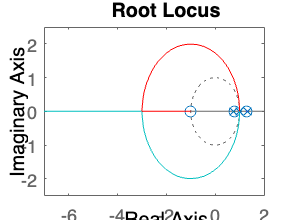


% Zonder regelaar
rlocus(Sd(1))

ps1 = pole(Sdtf(1)) % Het berekenen van de polen voor x

ps1 =     1.3210
    1.0000
    0.9929
    0.7555


% We merken op dat er reeds een pool op 1 ligt. Dit maakt dat voor de
% controle van de positie er automatisch zero-statische fout is VOOR HET SYSTEEM.
% MAAR: Nog niet voor de perturbaties een zero-static-error. Hiervoor zou
% er een pool in de regelaar moeten zijn.
zs1 = zero(Sdtf(1)) % Het berekenen van de nulpunten voor x

zs1 =    -0.9970
    1.2810
    0.7807



% Tests (niet goed)
% Rd1 = zpk([ps1(1:2)],[zs1(1),zs1(3),0],0.1,Ts);
% Rd1 = zpk([ps1(1:3)],[zs1(1),zs1(3),0,0.5],1,Ts);
% Rd1 = zpk([ps1(1),1.04,ps1(3)],[zs1(1),0,zs1(3),-0.5],199,Ts);
% Rd1 = zpk([ps1(1),1.04,ps1(3)],[zs1(1),0.5,zs1(3),-0.5],94.6,Ts); % Kracht te groot
% Rd1 = zpk([ps1(1),1.04,ps1(3)],[zs1(1),0.7,zs1(3),-0.7],60,Ts); % 60 ipv 60.6 voor reserve (niet imaginaire component polen)
% Rd1 = zpk([ps1(1),1.3,ps1(3)],[zs1(1),0.7,zs1(3),-0.7],15.6,Ts);
% Rd1 = zpk([ps1(1),1.3,ps1(3)],[zs1(1),0.7,zs1(3),0],8.97,Ts);
% Rd1 = zpk([ps1(1),1.3,ps1(3)],[zs1(1),0.7,zs1(3),0.2],7.06,Ts);
% Rd1 = zpk([ps1(1),1.3,ps1(3)],[zs1(1),0.75,zs1(3),0.2],5.6,Ts);
% Rd1 = zpk([ps1(1),1.3,ps1(3)],[zs1(1),0.75,zs1(3),0.29],4.91,Ts); % Alle 'arbitraire' polen en nulpunten geoptimaliseerd naar minimale fout % Probleem: Pool in negatief halfvlak: Oscillaties met de samplefrequentie
% Rd1 = zpk([ps1(1),1.3,ps1(3)],[0,0.51,zs1(3)],8.39,Ts); Alternatief, niet geïmplementeerd in Python.

% Positie controller
Rd1 = zpk([ps1(1),1.3,ps1(3)],[0.2,0.75,zs1(3),0.07],2.06,Ts);


% Polen:
%   - De pool op het nulpunt in 0.78 zorgt voor connectie van de pool er
%   links van met de takken er rechts van, waardoor de polen buiten de
%   eenheidscirkel naar binnen getrokken kunnen worden door een bepaalde
%   gain te kiezen.
%   - Spreiding van de polen in 0.29 en 0.75 zorgt ervoor dat de gain groot
%   gekozen kan worden zonder dat deze polen een imaginaire component
%   krijgen.
%   - De pool op het linker nulpunt zorgt ervoor dat er geen takken in die
%   buurt ontstaan.
% Nulpunten:
%   - Het nulpunt op de meest rechtse pool van het systeem bevriest deze pool.
%   - Het nulpunt in 1.3 zorgt ervoor dat de polen binnen de
%   eenheidscirkel kunnen worden getrokken voor een bepaalde waarde van de
%   gain.
%   - Het nulpunt op de pool van het systeem in 0.9929 zorgt ervoor dat de
%   plaats waar de polen binnen de eenheidscirkel komen en samenkomen op de
%   horizontale as meer naar links ligt, waardoor het systeem iets sneller
%   wordt. We wensen een traag systeem, maar te traag is ook niet goed,
%   want dan wint het misschien niet meer tegen de constante perturbaties
%   in het systeem).
% Gain:
%   We wensen de polen binnen de eenheidscirkel te plaatsen en kiezen
%   ervoor om deze eveneens op de reële as te laten vallen teneinde geen
%   imaginair component te verkrijgen. Daardoor wordt het oscillair gedrag
%   vermeden. Om de waarde van de gain te bepalen werd de rootlocus geplot
%   en de gain bepaald op de positie waar de twee rechtse krommes elkaar
%   binnen de eenheidscirkel raken. We vinden dat een gain van 60.6
%   vereist is en steken deze onmiddelijk in de definitie van Rd1. 60.6 is
%   niet exact de juiste waarde om geen imaginaire component te hebben (dit
%   zien we ook aan een lichte oscillatie in de lsim). Deze beschouwen we
%   echter als verwaarloosbaar. De polen in -0.7 en 0.7 werden gespreden
%   zodat bij de gekozen gain van 60.6 ze nog niet loskomen van de reële
%   as. Dit zou wel het geval zijn mochten ze dichter bij elkaar liggen.

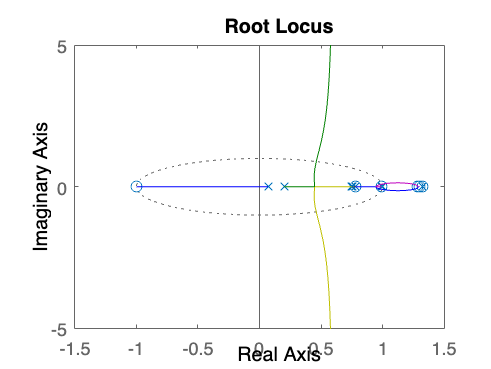

rlocus(Rd1*Sd(1))


SdCl_pos_Loop = minreal(feedback(Rd1*Sdtf,[1 0]))

SdCl_pos_Loop =
 
  From input "u" to output...
                 0.0046742 (z+0.997) (z-1.281) (z-1.3)
   x:  ---------------------------------------------------------
       (z-0.0009785) (z-0.4369) (z-0.4585) (z-0.9069) (z-0.9723)
 
                            0.011745 (z+0.997) (z-1)^2 (z-1.3)
   theta:  --------------------------------------------------------------------
           (z-0.0009785) (z-0.4369) (z-0.4585) (z-0.7807) (z-0.9069) (z-0.9723)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



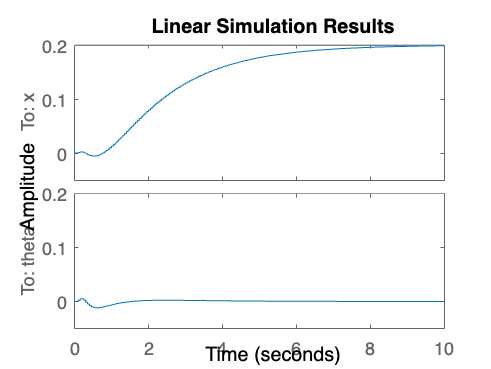

% Minreal vereenvoudigt de uitdrukking om het overzicht te bewaren.
% Enkel een feedback plaatsen op de positie door [1 0]

% Tijdspanne groter maken want dit is een tragere controller dan die van de
% hoek (om op die manier de controllers te scheiden in het tijdsdomein)
t = 0:Ts:10;
lsim(minreal(feedback(Rd1*Sdtf,[1 0])),[0.2 0.2 0.2*ones(1,length(t)-2)],t)

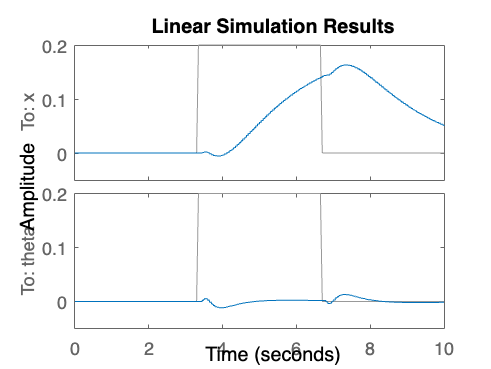

lsim(minreal(feedback(Rd1*Sdtf,[1 0])),[zeros(1,length(t)/3) 0.2*ones(1,length(t)/3) zeros(1,length(t)/3)],t)

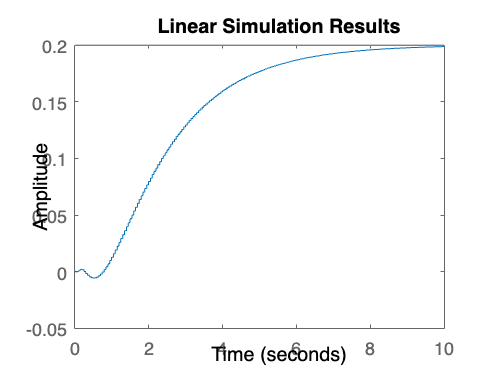

% Het systeem volgt de opgelegde waarde.

% Er worden geen impulsen of stappen aangelegd aangezien de hoek in
% realiteit niet zo'n verloop heeft. Daarom wordt gebruikgemaakt van lsim.
lsim(minreal(feedback(Rd1*Sdtf(1),1)),[0.2 0.2 0.2*ones(1,length(t)-2)],t) % Output y

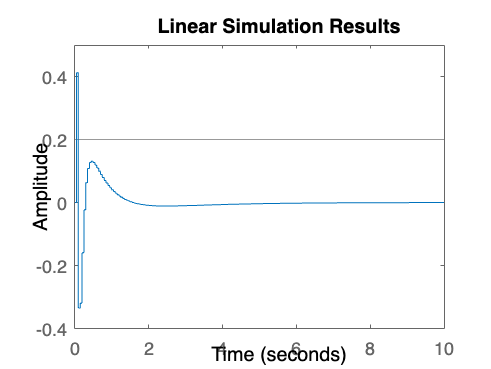

lsim(minreal(feedback(Rd1,Sdtf(1))),[0.2 0.2 0.2*ones(1,length(t)-2)],t) % Kracht F

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 2*10^2);

% Define parameters and modes
n_samples = 100;
ts = (0:n_samples-1)*Ts;
mode = CLASSICAL_COMB;
[~,G1] = zero(Rd1);
[~,G2] = zero(Rd2);
set_mode_params(arduino, mode, 0, cat(1, G1,cat(1,zero(Rd1),pole(Rd1)),G2, cat(1, zero(Rd2), pole(Rd2))));
reset_system(arduino);

w = 1.5;
set_mode_params(arduino, mode, w, cat(1, G1,cat(1,zero(Rd1),pole(Rd1)),G2, cat(1, zero(Rd2), pole(Rd2))));

reset_system(arduino);
Y = get_response(arduino, w, n_samples);
close_connection(arduino)
clear arduino

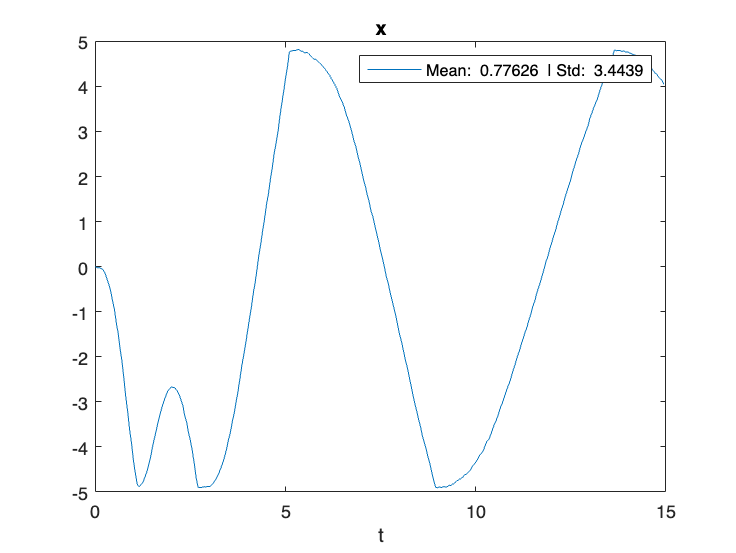

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
start = find(abs(x-w)<0.1,1);
figure; plot(ts, x); title("x"); xlabel('t')
legend(join(["Mean: ",num2str(mean(x(start:end)))," | Std: ",num2str(std(x(start:end)))]))

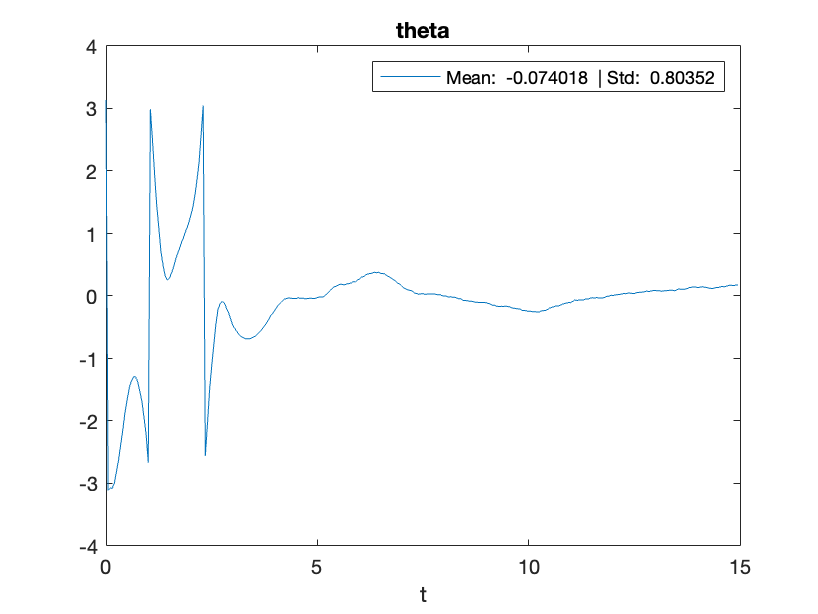

figure; plot(ts, theta); title("theta"); xlabel('t')
legend(join(["Mean: ",num2str(mean(theta))," | Std: ",num2str(std(theta))]))

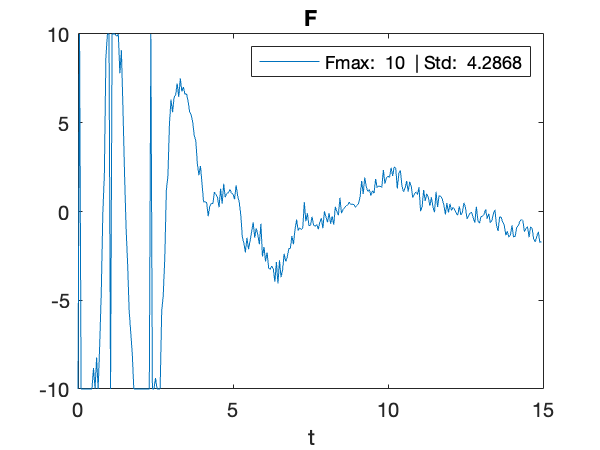

figure; plot(ts, u); title("F"); xlabel('t')
legend(join(["Fmax: ",num2str(max(abs(u)))," | Std: ",num2str(std(u))]))

% Soms verschijnt er een initiële piek voor de kracht (F). Gezien dit
% slechts om een piek gaat vormt dit geen probleem. Het werkelijke systeem
% (met een limitatie op de kracht) zal zich misschien licht anders
% gedragen, maar de hoek zal toch gestabiliseerd worden.

## State Observer

% Bovenaan al gecontroleerd of het systeem observeerbaar is
ps_d1 = [0,0,0.01,0.01]; % Uitzoeken waarom we die nulpunten nemen. Negatieve nulpunt nagaan of het een probleem kan vormen
L1 = place(Sd.A', Sd.C', ps_d1);
L1 = L1';

ps_d2 = [0.7,0.8,zs1(3),zs1(3)]; % Uitzoeken waarom we die nulpunten nemen. Negatieve nulpunt nagaan of het een probleem kan vormen
L2 = place(Sd.A', Sd.C', ps_d2);
L2 = L2';

eig(Sd.A-L1*Sd.C)

ans =     0.0100
    0.0100
   -0.0000
    0.0000


eig(Sd.A-L2*Sd.C)

ans =     0.8000
    0.7000
    0.7807
    0.7807


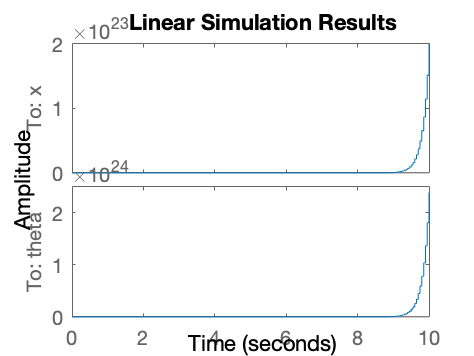

x0 = [0;0;pi;0];
t = 0:Ts:10;
u = zeros(1, length(t));
figure;
lsim(Sd, u, t, x0);

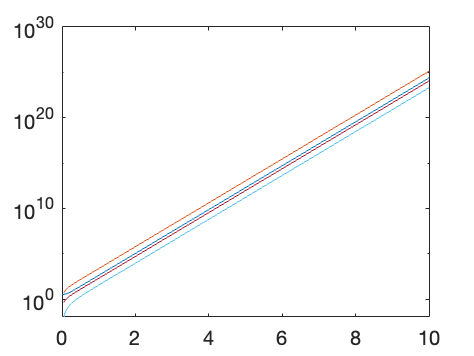

observer1 = ss(Sd.A - L1*Sd.C, [Sd.B, L1], eye(4,4), 0, Ts);
observer2 = ss(Sd.A - L2*Sd.C, [Sd.B, L2], eye(4,4), 0, Ts);
y = lsim(Sd, u, t, x0);
u_obs = [u; y']; % redefine the input

xhat1 = lsim(observer1, u_obs, t, x0);
xhat2 = lsim(observer1, u_obs, t, x0);
% define a system to directly compute x (C = I)
sys_all = ss(Sd.A, Sd.B, eye(4,4), 0, Ts);
x = lsim(sys_all, u, t, x0);
figure;
semilogy(t,x,t,xhat1); hold on
semilogy(t,x,t,xhat2);

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 2*10^3);
% Define parameters and modes
n_samples = 100;
ts = (0:n_samples-1)*Ts;
mode = OBSERVER_TEST;
[~,G1] = zero(Rd1);
[~,G2] = zero(Rd2);
w = 0;
set_mode_params(arduino, mode, w, cat(1, G1,cat(1,zero(Rd1),pole(Rd1)),G2, cat(1, zero(Rd2), pole(Rd2)),reshape(L1,[],1),reshape(Sd.A,[],1),reshape(Sd.B,[],1),reshape(Sd.C,[],1),reshape(L2,[],1)));
reset_system(arduino);
Y = get_response(arduino, w, n_samples); % Kolom 4 tot 7 zijn de geobserveerde waarden -> Plots mee maken om te zien of onze observator correct geïmplementeerd is
close_connection(arduino)
clear arduino

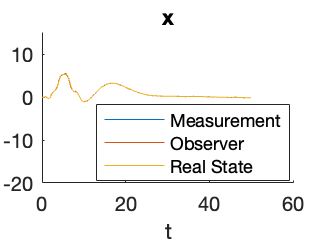

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
x_hat = Y(4,:); v_hat = Y(5,:); theta_hat = Y(6,:); theta_dot_hat = Y(7,:);
real_x = Y(8,:); real_v = Y(9,:); real_theta = Y(10,:); real_theta_dot = Y(11,:);

figure; hold on; plot(ts, x, ts, x_hat, ts, real_x); title("x"); xlabel('t'); ylim([-20 15])
legend("Measurement","Observer","Real State",'Location','best'); 

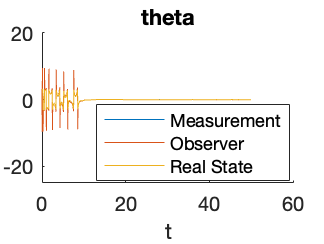

figure; hold on; plot(ts, theta, ts, theta_hat, ts, real_theta); title("theta"); xlabel('t'); ylim([-25 20])
legend("Measurement","Observer","Real State",'Location','best');

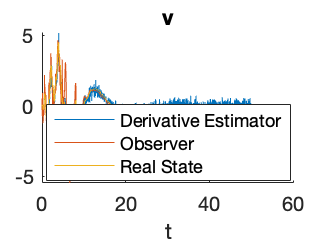


% Derivative estimator
v_est = ( x(2:end)-x(1:end-1) )/Ts;
figure; hold on; plot(ts(2:end), v_est, ts, v_hat, ts, real_v); title("v"); xlabel('t');
legend("Derivative Estimator","Observer","Real State",'Location','best');

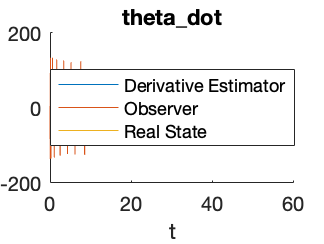

theta_dot_est = ( theta(2:end)-theta(1:end-1) )/Ts;
figure; hold on; plot(ts(2:end), theta_dot_est, ts, theta_dot_hat, ts, real_theta_dot); title("theta\_dot"); xlabel('t');
legend("Derivative Estimator","Observer","Real State",'Location','best');

## State Space Feedback

% P = [-0.8, -0.7, -0.6, -0.5]; % Desired position of the poles
% Kd = place(Sd.A, Sd.B, exp(P*Ts))

% Linear Quadratic regulator
% Kost Matrix - Hoek ctrl belangrijker maken dan pos ctrl
%Q = diag([6,0,1000,0]); 
Q = diag([38,0,10000,0]);

R = 1; % Weight van de input

[Kd,S,e] = dlqr(Sd.A,Sd.B,Q,R)

Kd =    -2.8053   -5.5472   58.7641    7.0545


S = 	1.0e+04 *

    0.1476    0.1396   -0.1525   -0.0588
    0.1396    0.2518   -0.2331   -0.1065
   -0.1525   -0.2331    2.1965    0.1459
   -0.0588   -0.1065    0.1459    0.0483


e =    0.9722 + 0.0264i
   0.9722 - 0.0264i
   0.3414 + 0.3169i
   0.3414 - 0.3169i



% System in Closed Loop (CL)
Adcl = Sd.A-Sd.B*Kd;
sysdcl = ss(Adcl,Sd.B,Sd.C,0,Ts);

% Berekening Kcl
Acl = Sd.A-Sd.B*Kd;
Bcl = Sd.B;
Ccl = Sd.C;
I = eye(size(Sd.A));
Kcl = Ccl*(I-Acl)^-1*Bcl;
Kcl = Kcl(1)

Kcl = -0.3565

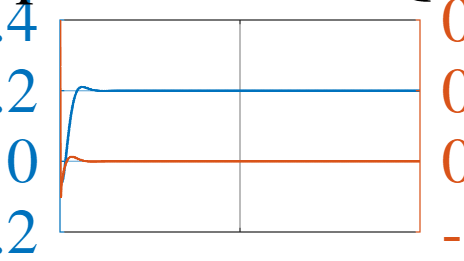

ts = 0:Ts:100;
SSF = ss(Sd.A-Sd.B*Kd,Sd.B,Sd.C,Sd.D,Ts,'statename',states,'inputname',inputs,'outputname',outputs);
r = [0.2/Kcl*ones(size(ts))];
figure
[y,t,x]=lsim(SSF,r,ts,[0 0 0.1 0]);
[AX,H1,H2] = plotyy(t,y(:,1),t,y(:,2),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
title('Step Response with LQR Control')

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 2*10^3);
% Define parameters and modes
n_samples = 10;
ts = (0:n_samples-1)*Ts;
mode = STATE_SPACE;
[~,G1] = zero(Rd1);
[~,G2] = zero(Rd2);
w = 0;
set_mode_params(arduino, mode, w, cat(1,reshape(Kd,[],1),reshape(L1,[],1),reshape(Sd.A,[],1),reshape(Sd.B,[],1),reshape(Sd.C,[],1),reshape(L2,[],1)));

reset_system(arduino);
Y = get_response(arduino, w, n_samples);
close_connection(arduino)
clear arduino

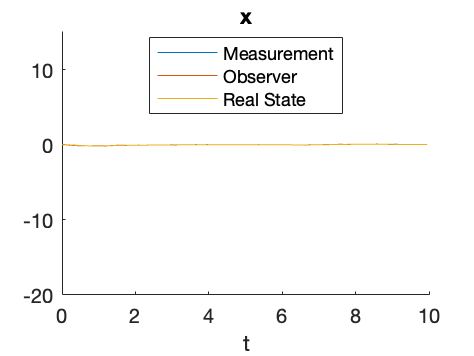

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
x_hat = Y(4,:); v_hat = Y(5,:); theta_hat = Y(6,:); theta_dot_hat = Y(7,:);
real_x = Y(8,:); real_v = Y(9,:); real_theta = Y(10,:); real_theta_dot = Y(11,:);

figure; hold on; plot(ts, x, ts, x_hat, ts, real_x); title("x"); xlabel('t'); ylim([-20 15])
legend("Measurement","Observer","Real State",'Location','best'); 

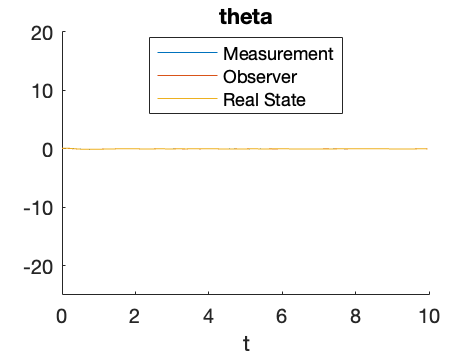

figure; hold on; plot(ts, theta, ts, theta_hat, ts, real_theta); title("theta"); xlabel('t'); ylim([-25 20])
legend("Measurement","Observer","Real State",'Location','best');

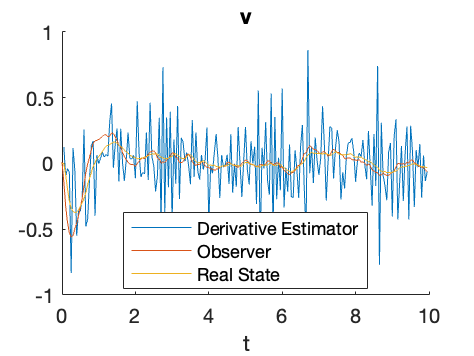


% Derivative estimator
v_est = ( x(2:end)-x(1:end-1) )/Ts;
figure; hold on; plot(ts(2:end), v_est, ts, v_hat, ts, real_v); title("v"); xlabel('t');
legend("Derivative Estimator","Observer","Real State",'Location','best');

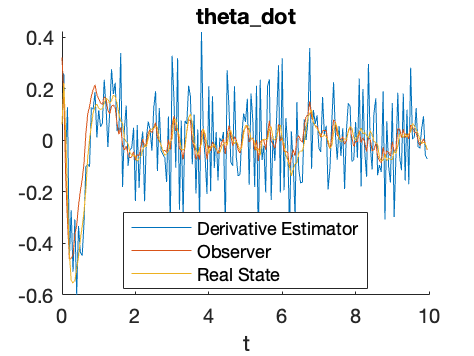

Ae =     1.0000    0.0498    0.0034    0.0001         0         0
         0    0.9909    0.1349    0.0034         0         0
         0   -0.0006    1.0392    0.0507         0         0
         0   -0.0229    1.5795    1.0392         0         0
    1.0000         0         0         0    1.0000    1.0000
         0         0    1.0000         0    1.0000    1.0000


Be =     0.0023
    0.0908
    0.0057
    0.2292
         0
         0


Ce =      1     0     0     0     0     0
     0     0     1     0     0     0


De =      0
     0


poles_Ke =    0.9722 + 0.0264i
   0.9722 - 0.0264i
   0.3414 + 0.3169i
   0.3414 - 0.3169i
   0.4000 + 0.0000i
   0.5000 + 0.0000i


Ke =   151.7545    9.8338  145.4648    2.0769  162.9071  150.9129


Kecl = 1.1882

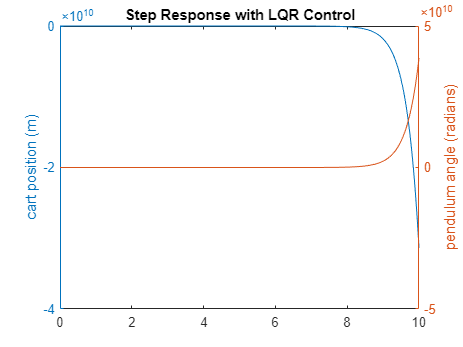

Ae =     1.0000    0.0498    0.0034    0.0001         0         0
         0    0.9909    0.1349    0.0034         0         0
         0   -0.0006    1.0392    0.0507         0         0
         0   -0.0229    1.5795    1.0392         0         0
    1.0000         0         0         0    1.0000    1.0000
         0         0    1.0000         0    1.0000    1.0000


Be =     0.0023
    0.0908
    0.0057
    0.2292
         0
         0


Ce =      1     0     0     0     0     0
     0     0     1     0     0     0


De =      0
     0


poles_Ke =    0.9722 + 0.0264i
   0.9722 - 0.0264i
   0.3414 + 0.3169i
   0.3414 - 0.3169i
   0.4000 + 0.0000i
   0.5000 + 0.0000i


Ke =   151.7545    9.8338  145.4648    2.0769  162.9071  150.9129


Kecl = 1.1882

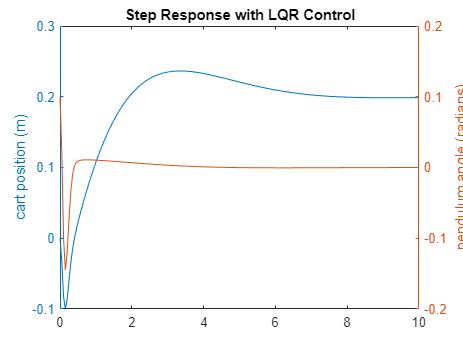

Ae =     1.0000    0.0498    0.0034    0.0001         0         0
         0    0.9909    0.1349    0.0034         0         0
         0   -0.0006    1.0392    0.0507         0         0
         0   -0.0229    1.5795    1.0392         0         0
    1.0000         0         0         0    1.0000    1.0000
         0         0    1.0000         0    1.0000    1.0000


Be =     0.0023
    0.0908
    0.0057
    0.2292
         0
         0


Ce =      1     0     0     0     0     0
     0     0     1     0     0     0


De =      0
     0


poles_Ke =   112.0198    6.2646  108.3168    3.1394  111.5096  111.5096


Ke = 	1.0e+09 *

   -1.8436   -2.7150    0.6959    1.0759    3.9304   -4.1885


Kecl = 4.2645e-10

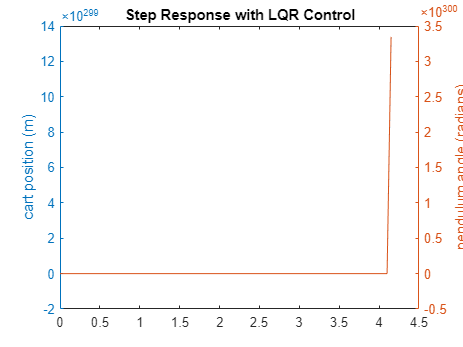

Ae =     1.0000    0.0498         0
         0    0.9909         0
    1.0000         0    1.0000


Be =     0.0023
    0.0908
         0


Ce =      1     0     0


De = 0

poles_Ke =    11.2272    3.2825    0.8504


Ke = 	1.0e+03 *

    4.3472   -0.2450    0.7698


Kecl = 0

theta_dot_est = ( theta(2:end)-theta(1:end-1) )/Ts;
figure; hold on; plot(ts(2:end), theta_dot_est, ts, theta_dot_hat, ts, real_theta_dot); title("theta\_dot"); xlabel('t');
legend("Derivative Estimator","Observer","Real State",'Location','best');

## Extended State Space Feedback (I)

AE = [Sd.A,zeros(4,1);Sd.C(1,:),1]

AE =     1.0000    0.0498    0.0034    0.0001         0
         0    0.9909    0.1349    0.0034         0
         0   -0.0006    1.0392    0.0507         0
         0   -0.0229    1.5795    1.0392         0
    1.0000         0         0         0    1.0000


BEu0 = [Sd.B;Sd.D(1)]

BEu0 =     0.0023
    0.0908
    0.0057
    0.2292
         0


BE = [Sd.B, zeros(4,1); Sd.D(1), -1]

BE =     0.0023         0
    0.0908         0
    0.0057         0
    0.2292         0
         0   -1.0000


CE = [Sd.C(1,:),0]

CE =      1     0     0     0     0


DE = [Sd.D]

DE =      0
     0



KE = dlqr(AE,BEu0,diag([38,0,10000,0,10]),1)

KE =   -34.1810  -20.8118   80.4138   13.4508   -1.3464


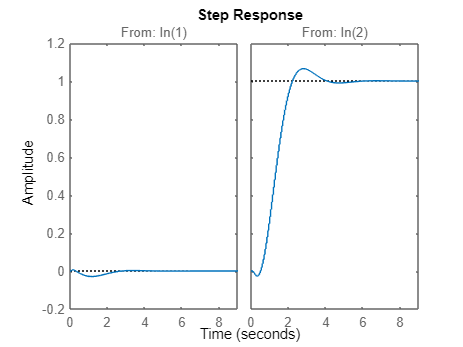

Kd = KE(1:end-1);
Ki = KE(end);

sysE_cl = ss(AE - BEu0 * KE, BE, CE, 0, Ts);
step(sysE_cl)


% Alternative
z = tf('z',Ts);
RI = Ki / (z - 1)

RI =
 
  -1.346
  ------
  z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.



sysd_cl = ss(Sd.A - Sd.B * Kd, Sd.B, Sd.C, 0, Ts)  % Evt hier Bdu0

sysd_cl =
 
  A = 
             x1        x2        x3        x4
   x1     1.078     0.097   -0.1791  -0.03046
   x2     3.102      2.88    -7.163    -1.217
   x3    0.1949    0.1181    0.5808  -0.02604
   x4     7.834     4.747    -16.85    -2.044
 
  B = 
             u1
   x1  0.002269
   x2   0.09075
   x3  0.005702
   x4    0.2292
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.05 seconds
Discrete-time state-space model.



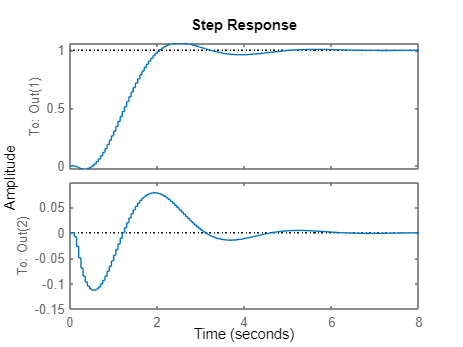

sysE_cl = feedback(RI*sysd_cl, [1, 1]);
step(sysE_cl)

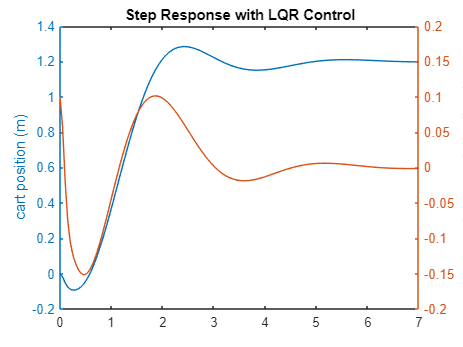

ts = 0:Ts:7;
r = [1.2*ones(size(ts))];
figure
[y_EI,t,x]=lsim(sysE_cl,r,ts,[0 0 0.1 0 0]);
[AX,H1,H2] = plotyy(t,y_EI(:,1),t,y_EI(:,2),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
title('Step Response with ESS I')

%% Simulatie SSF
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 2*10^3);
n_samples = 20;
ts = (0:n_samples-1)*Ts;
mode = EXTENDED;
[~,G1] = zero(Rd1);
[~,G2] = zero(Rd2);
w = 0;
set_mode_params(arduino, mode, w, cat(1,reshape(Kd,[],1),Ki,reshape(L1,[],1),reshape(Sd.A,[],1),reshape(Sd.B,[],1),reshape(Sd.C,[],1),reshape(L2,[],1)));
reset_system(arduino);
Y = get_response(arduino, w, n_samples);
close_connection(arduino)
clear arduino

## Extended State Space Feedback (PI)

% Make it even faster with a PI by placing a zero on the slowest pole of the extended sys
P_ESS_I = log(pole(sysE_cl))/Ts % Slowest one has Im component

P_ESS_I =  -15.2959 +16.1022i
 -15.2959 -16.1022i
  -0.8157 + 1.9394i
  -0.8157 - 1.9394i
  -1.2792 + 0.0000i


z_PI = real(P_ESS_I(3))

z_PI = -0.8157

z_PI = (P_ESS_I(end))

z_PI = -1.2792

Kp = Ki / (1 - z_PI)

Kp = -0.5907

Kcorr = Kd - Kp * Sd.C(1,:)

Kcorr =   -33.5903  -20.8118   80.4138   13.4508



%sysE_PI_cl = ss(AE - BEu0 * Kcorr, BE, CE, Ddu0, Ts);
%step(sysE_PI_cl)

sysd_PI_cl = ss(Sd.A - Sd.B * Kcorr, Sd.B, Sd.C, 0, Ts);
z = tf('z',Ts);
R_PI = Kp + Ki/(z-1)

R_PI =
 
  -0.5907 z - 0.7556
  ------------------
        z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.



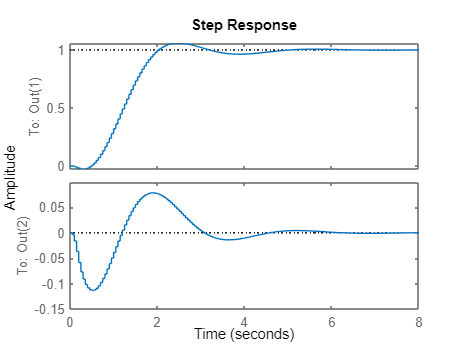

sysE_PI_cl = feedback(R_PI * sysd_PI_cl, [1,1]);

step(sysE_PI_cl)   % Will now be a little bit faster

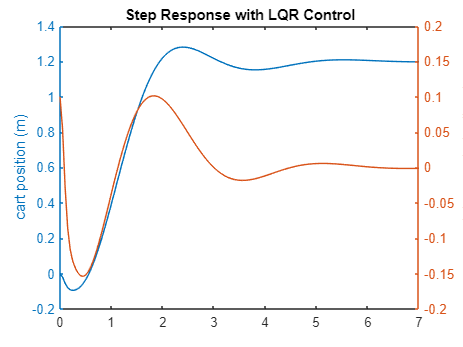

ts = 0:Ts:7;
r = [1.2*ones(size(ts))];
figure
[y_EPI,t,x]=lsim(sysE_PI_cl,r,ts,[0 0 0.1 0 0]);
[AX,H1,H2] = plotyy(t,y_EPI(:,1),t,y_EPI(:,2),'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)')
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)')
title('Step Response with ESS PI')

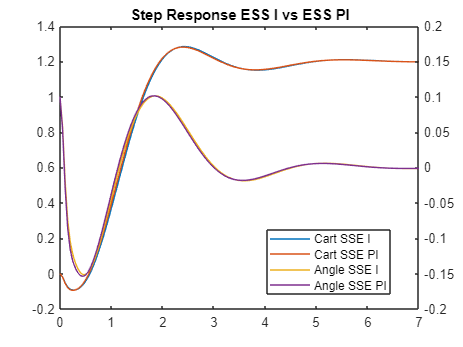

[AX,H1,H2] = plotyy([t,t],[y_EI(:,1),y_EPI(:,1)],[t,t],[y_EI(:,2),y_EPI(:,2)],'plot');
title('Step Response ESS I vs ESS PI');
legend('Cart SSE I','Cart SSE PI','Angle SSE I','Angle SSE PI','Location','best');

% De respons bij ESS PI is net iets sneller dan deze bij ESS I